# Noncollaborative Bluetooth LE Coexistence with WLAN Signal Interference

This example shows how to simulate Bluetooth low energy (LE) noncollaborative coexistence with WLAN interference by using Bluetooth® Toolbox and Communications Toolbox™ Wireless Network Simulation Library.

Using this example, you can:

- Create and configure a Bluetooth LE piconet with Central and Peripheral nodes.

- Analyze the performance of the Bluetooth LE network with and without WLAN interference.

- Visualize Bluetooth LE coexistence with WLAN interference for each Peripheral node by implementing adaptive frequency hopping (AFH).

- Visualize the status (good or bad) and success rate (recent and cumulative) of each channel.

Additionally, you can use this example script to perform these tasks.

- Add WLAN Signal Using WLAN Toolbox Features

- Capture Bluetooth LE Packets to PCAP or PCAPNG file

- Add Custom Channel Classification

- Add Multiple Peripheral Nodes To A Piconet

## Noncollaborative Bluetooth LE-WLAN Coexistence Scenario

Interference between Bluetooth and WLAN can be mitigated by two types of coexistence mechanisms: collaborative and noncollaborative. Noncollaborative coexistence mechanisms do not exchange information between two wireless networks. Collaborative coexistence mechanisms collaborate and exchange network-related information between two wireless networks. These coexistence mechanisms are applicable only after a WLAN or Bluetooth piconet is established and the data is to be transmitted. This example demonstrates a noncollaborative  AFH technique deployed between Bluetooth LE and WLAN nodes to mitigate interference. AFH enables a Bluetooth node to adapt to its environment by identifying fixed sources of WLAN interference and excluding them from the list of available channels. For more information about coexistence between Bluetooth LE and WLAN, see [Bluetooth-WLAN Coexistence](docid:bluetooth_ug#mw_70305389-b34c-4c02-85c4-4b07b05a1103).

The Bluetooth LE piconet consists of one Bluetooth LE Central node and one Peripheral node. The scenario consists of two WLAN nodes, which introduce interference in the Bluetooth LE signal. The example simulates this coexistence scenario between Bluetooth LE and WLAN.

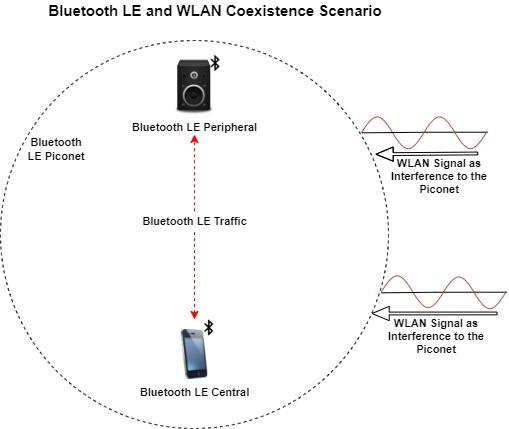

## Check for Support Package Installation

Check if the 'Communications Toolbox Wireless Network Simulation Library' support package is installed.

wirelessnetworkSupportPackageCheck

## Configure Coexistence Scenario

Set the seed for the random number generator to `1` to ensure repeatability of results. The seed value controls the pattern of random number generation. Initializing the random number generator using the same seed assures the same result. For high-fidelity simulation results, change the seed value and average the results over multiple simulations.

rng(1,"twister");

Create a wireless network simulator object.

networkSimulator = wirelessNetworkSimulator.init;

Create a Bluetooth LE node and set the role to `"central"` by using the [bluetoothLENode](docid:bluetooth_ref#mw_9e947122-1ba1-401a-8e3c-d4b74ea1461b) object. Set the properties of the Central node.

centralNode = bluetoothLENode("central", ...
    Name="Central Node", ...
    Position=[5 0 0], ...                    % x-, y-, and z-coordinates in meters
    TransmitterPower=0);                     % In dBm

Create a Bluetooth LE node and set the role to `"peripheral"`. Set the properties of the Peripheral node.

peripheralNode = bluetoothLENode("peripheral", ...
    Name="Peripheral Node", ...                                  
    Position=[10 0 0], ...                          % x-, y-, and z-coordinates in meters
    TransmitterPower=0);                            % In dBm

Create a Bluetooth LE configuration object. Set the connection interval, active period, connection offset, and access address for each connection. Connection events are established for every connection interval duration throughout the simulation. The connection offset specifies the offset from the beginning of the connection interval. The active period specifies the active communication period for a connection after which connection event is ended. Assign the configuration to the Central and Peripheral nodes.

connectionConfig = bluetoothLEConnectionConfig;
connectionConfig.ConnectionInterval = 0.01;                         % In seconds
connectionConfig.ActivePeriod = 0.01;                               % In seconds
connectionConfig.ConnectionOffset = 0;                              % In seconds
connectionConfig.AccessAddress = "12345678";                        % In hexadecimal
configureConnection(connectionConfig,centralNode,peripheralNode);

### Configure Application Traffic

Create a [`networkTrafficOnOff`](docid:comm_ref#mw_0b2cd92a-350a-4264-9283-db5da34bd041) object to generate an On-Off application traffic pattern. Configure the On-Off application traffic pattern at the Central and Peripheral nodes by specifying the application data rate, packet size, and on state duration. Attach application traffic from the Central to the Peripheral nodes.

central2PeripheralTrafficSource = networkTrafficOnOff(...
    OnTime=inf, ...                                                  % In seconds
    DataRate=150, ...                                                % In Kbps
    PacketSize=100, ...                                              % In bytes
    GeneratePacket=true);
addTrafficSource(centralNode,central2PeripheralTrafficSource, ...
    DestinationNode=peripheralNode.Name);

Attach application traffic from the Peripheral to the Central nodes.

peripheral2CentralTrafficSource = networkTrafficOnOff(...
    OnTime=Inf, ...
    DataRate=150, ...
    PacketSize=100, ...
    GeneratePacket=true);
addTrafficSource(peripheralNode,peripheral2CentralTrafficSource, ...
    DestinationNode=centralNode.Name);

### Configure WLAN Signal Interference

To add WLAN signal interference, set the `enableWLANInterference` flag to true. 

enableWLANInterference = true;

Specify the number of WLAN nodes and their positions in the network. The WLAN nodes introduce interference in the network and do not model the PHY and MAC behavior.

Set the properties of the WLAN nodes. Specify the source of WLAN interference by using one of these options.

- `"Generated"` - To add a WLAN toolbox™ signal to interfere with the communication between Bluetooth LE nodes, select this option and uncomment the WLAN configuration object code.

- `"BasebandFile"` - To add a WLAN signal from a baseband file with the`.bb` extension to interfere with the communication between Bluetooth nodes, select this option. You can specify the file name using the `BasebandFile` input argument. If you do not specify a baseband file, the example adds the default file, `WLANHESUBandwidth20` to the WLAN signal.

To determine the path loss of the channel during the transmission, the example uses the distance between the nodes. Create WLAN nodes to introduce interference in the network by using the [`helperInterferingWLANNode`](matlab:edit('helperInterferingWLANNode.m')) helper object.

if enableWLANInterference
    wlanInterferenceSource = "BasebandFile";
    numWLANNodes = 2;
    wlanNodePositions = [0 7 5; 10 8 5];                         % x-, y-, and z-coordinates in meters
    wlanCenterFrequency =  [2.412e9; 2.442e9];                  % Center frequency (in Hz) based on the channel of operation
    wlanNodes = helperInterferingWLANNode.empty(0,numWLANNodes);
    for wlanIdx=1:numWLANNodes
        wlanNodeObj = helperInterferingWLANNode(...
            WaveformSource=wlanInterferenceSource, ...
            Position=wlanNodePositions(wlanIdx,:), ...
            Name="WLAN node", ...
            TransmitterPower=15, ...                            % In dBm
            CenterFrequency=wlanCenterFrequency(wlanIdx), ...
            Bandwidth = 20e6, ...                               % In Hz
            SignalPeriodicity=0.0029);                          % In seconds
% 
% %       To add interfering signal generated using WLAN Toolbox, uncomment this code
%         if strcmpi(wlanInterferenceSource, "Generated")
%             wlanNodeObj.FormatConfig = wlanHTConfig("ChannelBandwidth","CBW20");
%         end
%
        wlanNodes(wlanIdx) = wlanNodeObj;
    end
end

### Create Bluetooth LE Network

Create a Bluetooth LE network consisting of the Bluetooth LE nodes and any WLAN interfering nodes. 

bluetoothNodes = [centralNode peripheralNode];

Add the Bluetooth and any WLAN nodes to the simulator.

addNodes(networkSimulator,bluetoothNodes);
if enableWLANInterference 
    addNodes(networkSimulator,wlanNodes);
end

## Configure Visualization and Channel Classification

Specify the simulation time by using the `simulationTime` variable. Enable the option to visualize the Bluetooth LE coexistence with WLAN and the channel hopping sequence.

simulationTime = 2;             % In seconds

To implement channel classification, enable the `enableChannelClassification` variable.

enableChannelClassification = true;

### Schedule Channel Classification

The Bluetooth LE signal transmitted in a particular channel suffers interference from the WLAN signals. The Bluetooth LE node pseudorandomly selects a new channel from the channel map by using frequency hopping. This example classifies the channels using the AFH algorithm only when you enable channel classification. For each Peripheral node, the Central node periodically classifies the channels as "good" or "bad" based on the total packets received and failed in that channel. If the current number of good channels is less than the preferred number of good channels, the example reclassifies all the bad channels as good channels.

This example implements channel classification by periodic evaluation of the packet failures of each channel. For each Peripheral node, create a channel classifier by using the [`helperBluetoothChannelClassification`](matlab:edit("helperBluetoothChannelClassification.m")) helper object and schedule the action for each Peripheral node. You can schedule a custom action in the simulation by using the [`scheduleAction`](docid:comm_ref#mw_42d06b2d-da83-4184-aebb-bf3d1080d346) object function of the [`wirelessNetworkSimulator`](docid:comm_ref#mw_d18d4a33-0cf8-49d9-abb5-a4cfa0de673d) object. For example, each time you call the simulator, you can schedule an action to plot the state transitions. Specify the function handle, input argument, absolute simulation time, and periodicity of the callback.

Create a function handle to classify the channel by using the [`classifyChannels`](matlab:edit("helperBluetoothChannelClassification.m/classifyChannels")) object function of the [`helperBluetoothChannelClassification`](matlab:edit("helperBluetoothChannelClassification.m")) helper object. Schedule the channel classification for the periodicity of the callback by using the [`scheduleAction`](docid:comm_ref#mw_42d06b2d-da83-4184-aebb-bf3d1080d346) object function of the [`wirelessNetworkSimulator`](docid:comm_ref#mw_d18d4a33-0cf8-49d9-abb5-a4cfa0de673d) object. To perform a channel classification for the Peripheral nodes, create and schedule the action for individual destinations.

if enableChannelClassification 
    classifierObj = helperBluetoothChannelClassification(...
        centralNode,peripheralNode,PERThreshold=50);
    classifyFcn = @(varargin) classifierObj.classifyChannels;
    userData = [];                                                            % User data needed to be passed to the callback function
    callAt = 0;                                                               % Absolute simulation time, in seconds
    periodicity = 125e-3;                                                     % In seconds
    
    scheduleAction(networkSimulator,classifyFcn,userData,callAt,periodicity); % Schedule channel classification
end

### Visualization

Enable the option to visualize the Bluetooth coexistence with WLAN and the channel hopping sequence.

enableVisualization = true;

Initialize coexistence visualization by using the [`helperVisualizeCoexistence`](matlab:edit("helperVisualizeCoexistence.m")) helper object. To update the channel map for each channel map update and the status of the channel for each packet reception, listeners are created by using the [`addlistener`](docid:matlab_ref#bulrzj5-1) function of the [`helperVisualizeCoexistence`](matlab:edit("helperVisualizeCoexistence.m")) helper object. When the `ChannelMapUpdated` and `PacketReceptionEnded` events are triggered at the Central node object, the listener listens to those events.

if enableVisualization && enableWLANInterference
    coexistenceVisualization = helperVisualizeCoexistence(networkSimulator,simulationTime,bluetoothNodes,wlanNodes);
elseif enableVisualization && ~enableWLANInterference
    coexistenceVisualization = helperVisualizeCoexistence(networkSimulator,simulationTime,bluetoothNodes);
end

## Simulation Results

Run the simulation for the specified time and display the channel hopping sequence in the Bluetooth LE channels and the interference due to the WLAN signals. Visualize the state transitions, status (good or bad), and success rate (recent and cumulative) of each channel. The recent success rate represents the cumulative success rates between each channel classification interval. The overall success rate represents the cumulative success rate throughout the simulation time.

run(networkSimulator,simulationTime);

### Retrieve Statistics

The example simulation generates these results.

- A run-time plot for each Central-Peripheral connection pair showing the status (good or bad) and success rate (recent and cumulative) of each channel.

- Channel classification statistics showing the total number of packets received and corrupted and the status (good or bad) of each channel for each classification interval.

- A bar plot for each peripheral showing the packet loss ratio and throughput between each channel map update.

- Application layer (APP), link layer (LL), and PHY statistics for Central and Peripheral nodes.

Retrieve the channel classification statistics by using the [`classificationStatistics`](matlab:edit('helperBluetoothChannelClassification/classificationStatistics')) object function of the [`helperVisualizeCoexistence`](matlab:edit('helperVisualizeCoexistence.m')) helper object. Use this object function to visualize the packet loss ratio and throughput between each channel map update for every Peripheral node. 

if enableChannelClassification && enableVisualization
    bluetoothLEChannelStats = classificationStatistics(coexistenceVisualization,centralNode,peripheralNode);
end

Get the Central and Peripheral node statistics by using the [`statistics`](docid:bluetooth_ref#mw_2dda2c46-7b37-43d1-b71c-27d10ac0a31d) object function.

centralStats = statistics(centralNode);
peripheralStats = statistics(peripheralNode);

The Bluetooth LE Central and Peripheral nodes avoid the interfered channels through channel classification and communicate with each other to avoid packet loss. The success rate is calculated at each Bluetooth LE channel. This example concludes that for high transmit power of a WLAN channel, the success rate of the respective Bluetooth LE channel is low. Therefore, these channels are not used for communication between Bluetooth LE Central and Peripheral nodes.

## Further Exploration

### Add WLAN Signal Using WLAN Toolbox Features

To add a WLAN signal using WLAN Toolbox features, set the value of `WaveformSource` parameter of the `wlanNodeObj` or a [`helperInterferingWLANNode`](matlab:edit('helperInterferingWLANNode.m')) object to "`Generated"`. Uncomment the code lines in the WLAN Signal Interference section. You can modify the WLAN packet format configuration object in the `FormatConfig` property of `wlanNodeObj` and assign it to the WLAN node. Set the bandwidth of the signal based on the assigned configuration object.

### Capture Bluetooth LE  Packets to PCAP or PCAPNG file

To capture the packets at any Bluetooth nodes in a packet capture (PCAP) or packet capture next generation (PCAPNG) file, add the following code before you run the simulation. The packets are captured into individual PCAP/PCAPNG files for each of the Bluetooth LE node. The name of the PCAP file for a node is in the format: <NodeName_NodeID_yyyyMMdd_HHmmss>.<file_extension>. Node ID is a unique number generated internally for each node. Node ID is a read-only property for all the nodes. Use the [`helperPacketCapture`](matlab:edit('helperPacketCapture.m')) object and specify the Bluetooth LE nodes to capture. Specify the file extension as "pcap" or "pcapng".

% clear packetCaptureObj; % Clear the packet capture handle if exists
% packetCaptureObj = helperPacketCapture(bluetoothNodes,"pcap");

### Add Custom Channel Classification

To add a custom channel classification algorithm, perform these steps:

- Create a custom channel classification object.

- Classify the channels by passing the classification function at an absolute simulation time or at a particular periodicity by using the [`scheduleAction`](docid:comm_ref#mw_42d06b2d-da83-4184-aebb-bf3d1080d346) object function.

- Instead of scheduling or calling the classification at certain simulation time instances, you can implement a custom channel classification algorithm by classifying the channels based on the status of the received packets.

- Update the status of the received packets by using the [`updateRxStatus`](matlab:edit('helperBluetoothChannelClassification/updateRxStatus')) object function.

- Classify the channels based on the status of the received packets by using the [`classifyChannels`](matlab:edit('helperBluetoothChannelClassification/classifyChannels')) object function.

### Add Multiple Peripheral Nodes To A Piconet

To add multiple Peripheral nodes to a piconet, perform these steps:

- Create Peripheral nodes by using the [bluetoothLENode](docid:bluetooth_ref#mw_9e947122-1ba1-401a-8e3c-d4b74ea1461b) object, setting the `Role` property to `"peripheral"`.

- Create a connection configuration by using the [`bluetoothLEConnectionConfig`](docid:bluetooth_ref#mw_4e46530f-eabd-4a7f-8cba-ac71504e1e43) object.

- Assign the configuration to the Central node and each Peripheral node.

- Generate and add application traffic at the Central and Peripheral nodes.

- Create a Bluetooth BR network with all the nodes.

- Enable channel classification at the Central node for each of the Peripheral nodes by creating an array of classifier objects.

- Schedule the action for each of the Peripheral nodes. Retrieve the statistics for all Peripheral nodes.

## Appendix

The example uses these helper functions:

- [helperInterferingWLANNode](matlab:edit('helperInterferingWLANNode.m')) - Configure and simulate interfering WLAN node

- [helperVisualizeCoexistence](matlab:edit('helperVisualizeCoexistence.m')) - Visualize the coexistence model

- [helperBluetoothChannelClassification](matlab:edit('helperBluetoothChannelClassification.m')) - Create an object to classify the Bluetooth LE channels

- [helperPacketCapture](matlab:edit('helperPacketCapture.m')) - Create an object to capture Bluetooth LE packets as PCAP/PCAPNG file

## References

- Bluetooth Technology Website. “Bluetooth Technology Website | The Official Website of Bluetooth Technology.” Accessed September 20, 2022. [https://www.bluetooth.com/](https://www.bluetooth.com/)

- Bluetooth Special Interest Group (SIG). "Bluetooth Core Specification". Version 5.3. [https://www.bluetooth.com/](https://www.bluetooth.com/)

- IEEE® Standard 802.15.2™. "Coexistence of Wireless Personal Area Networks with Other Wireless Devices Operating in Unlicensed Frequency Bands". *IEEE Recommended Practice for Information technology - Telecommunications and information exchange between systems - Local and metropolitan area networks - Specific requirements; IEEE Computer Society*

- IEEE P802.11ax™/D3.1. "Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications - Amendment 6: Enhancements for High Efficiency WLAN". *Draft Standard for Information technology - Telecommunications and information exchange between systems Local and metropolitan area networks - Specific requirements; LAN/MAN Standards Committee of the IEEE Computer Society*

- IEEE Std 802.11™. "Wireless LAN Medium Access Control (MAC) and Physical Layer (PHY) Specifications". *IEEE Standard for Information technology - Telecommunications and information exchange between systems - Local and metropolitan area networks - Specific requirements; LAN/MAN Standards Committee of the IEEE Computer Society*

*Copyright 2019-2022 The MathWorks, Inc.*